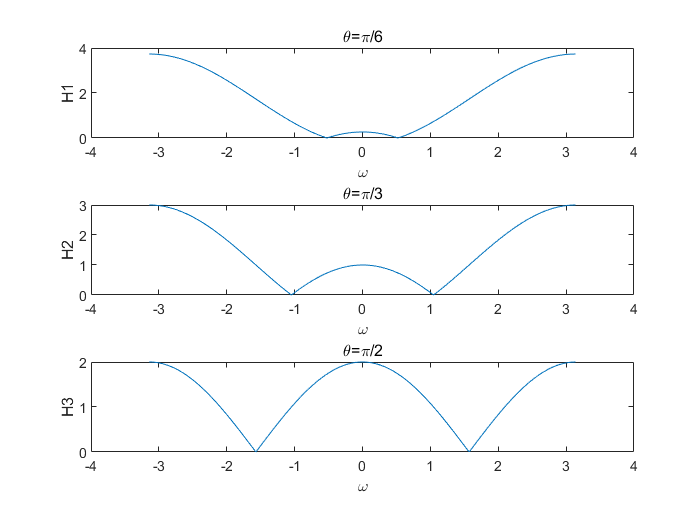

clear;close all;
w=-pi:0.01:pi;
z=exp(1j*w);

H1=1-2*cos(pi/6)*z.^(-1)+z.^(-2);
H2=1-2*cos(pi/3)*z.^(-1)+z.^(-2);
H3=1-2*cos(pi/2)*z.^(-1)+z.^(-2);

figure(1);
subplot(311);
plot(w,abs(H1));
title('\theta=\pi/6');xlabel('\omega');ylabel('H1');
subplot(312)

plot(w,abs(H2));
title('\theta=\pi/3');xlabel('\omega');ylabel('H2');
subplot(313)
plot(w,abs(H3));
title('\theta=\pi/2');xlabel('\omega');ylabel('H3');

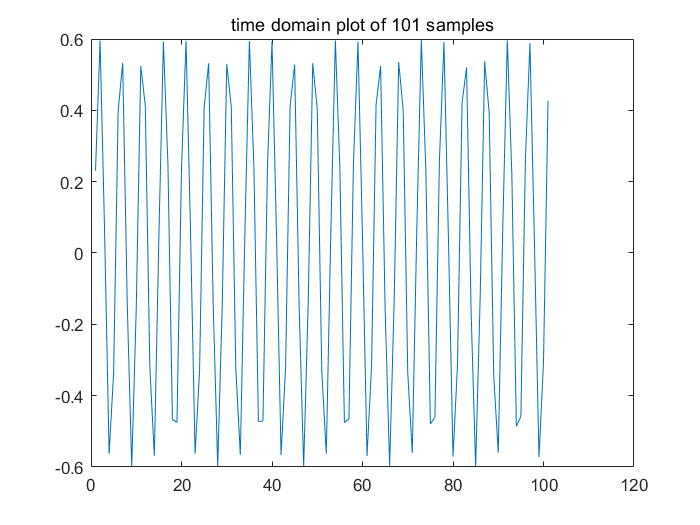

load nspeech1.mat;
% sound(nspeech1);
figure(2);
plot(nspeech1(100:200));title('time domain plot of 101 samples')

figure(3);
y1=nspeech1(100:1100);
[X1,w1]=DTFT(y1,1001);
subplot(311);
plot(w1,abs(X1));xlabel('\omega');title('DTFT of signal')
[Xmax,Imax]=max(abs(X1))

Xmax = 254.2287

Imax = 297

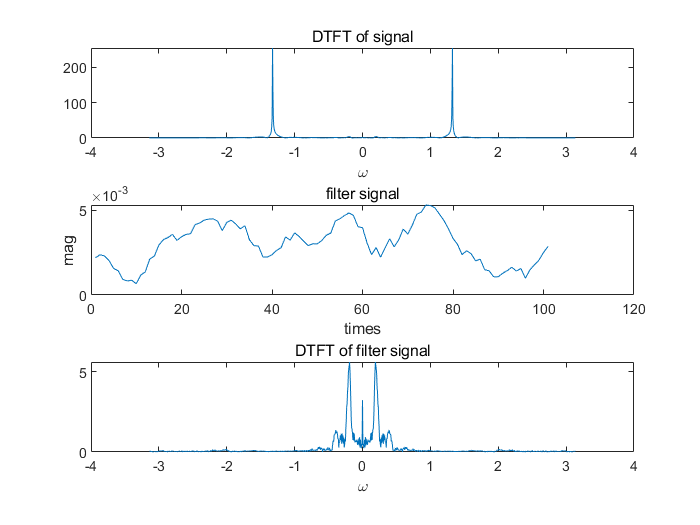

y2=FIRfilter(nspeech1);
subplot(312)
plot(y2(100:200));ylabel('mag');xlabel('times');title('filter signal')
subplot(313)
[X3,w3]=DTFT(y2(100:1100),0);
plot(w3,abs(X3));xlabel('\omega');title('DTFT of filter signal');

sound(y2);